## Input runData and modelData

tic
% Settings to run model
runData.filename = 'testgif.gif';
runData.runType = 'time';
runData.checkGeometry = true;
runData.plotSolution = true;
runData.hmax = 0.05;          % mesh size: default hmax = 0.15
runData.dataset = 'Diff_driven';  
runData.nEquations = 1;
runData.YZslice = "optimize1";

% Load material properties and sources
[modelData.Diff,modelData.Diff_info] = s4_loadProperties_EK(runData.dataset);
% Material assignment to model domains
modelData.materialIDs = [1,2,2]; % define differently if different material per face (# faces = 2, so 2 elements)

% Source assignment to model domains
modelData.sourceIDs = [1,1,1]; % define differently if different source term (more heat /concentration)
modelData.fixedSource = [0;0;0]; % Source terms, is zero for both subdomains. Change if different source terms. 
modelData.SourceValue = 7.97*10^9; % #/cm3 minimum concentration of NPs per injection volume to avoid toxicity (0.1% mass)

## 1+2: Create model, geometry and mesh

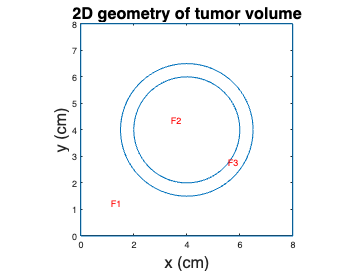

Elapsed time is 1.042111 seconds.


% Create PDE model
[model,modelData] = s1_createPDEModel(runData,modelData);
% Load test geometry
[model,~,centretumor,diametertumor] = t2_createGeometry2D(model,runData); % default = t2_creategeometry2D (circle tumor + part breast)

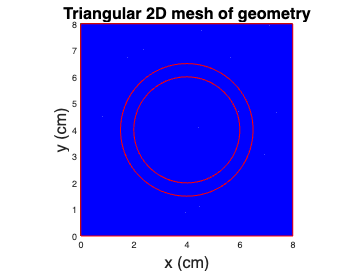

% Generate mesh
[model] = s3_createMesh2D(model,runData);

toc

Elapsed time is 1.330966 seconds.


## 3+4: Set BC, IC and time scale

tic
% Boundary conditions:      only applicable for outer boundaries 
runData.nBCs.neumann = 1;   % necessary to define if multiple neumann boundaries with different values
runData.BCs.neumann(1) = struct('edge',1:4,'q',0,'g',0); % flux breast [#NPs/m2*s] % must depend on conc. present to not become negative. Which BC?
%runData.BCs.neumann(2) = struct('edge',[2 3],'q',0,'g',0); %6 flux tumor [#NPs/m2*s]
runData.nBCs.dirichlet = 1;
runData.BCs.dirichlet(1) = struct('edge',[],'u',0);     % [] means isempty

%%%%%%% Initial conditions %%%%%%%%%%
% Initial conditions
[modelData.x0, modelData.y0, noSeeds] = t4_3_YZ_seedlocationssquare(runData,diametertumor,centretumor);
runData.nICs = 2;                  % necessary to define if multiple initial conditions different per face
modelData.Cinit_tumor = @(location)Cinit_NP2(location,modelData.x0,modelData.y0,modelData.SourceValue);
runData.IC(1) = struct('u',0,'Face',1);   % initial concentration of NPs in body = 0 [#NPs/m3]
runData.IC(2) = struct('u',modelData.Cinit_tumor,'Face',2:3);    % initial concentration of NPs in tumor: equation zero everywhere but at injection locations [#NPs/m3]
[model] = s4_2_loadBCIC(model,modelData,runData);
toc

Elapsed time is 0.160090 seconds.



%%%%% Time scale ******
h = 24*17; % number of hours % default total time  = 17*24 h
%T_end = 60*60*h;
runData.timePoints = 0:1:h;  % default stepsize = 1 h % compute in hours because diffusion terms have been changed to m2/h instead of m2/s (see loadXS_EK)

## 3+5: Solve system of PDE 

tic
% Solve PDE model
[~,results] = s5_NPDiffusion2D(model,modelData,runData);
modelData.Cresults = results.NodalSolution;              % results of solvepde function. Matrix with concentration of NPs for each meshnode (rows) per timestep (columns)      
Cresults = modelData.Cresults;
toc

Elapsed time is 193.530842 seconds.


## 6: Results: max, min average through tumour

% Calculate maximum, minimum and average results over time
modelData.solMin = min(modelData.Cresults);
modelData.solMax = max(modelData.Cresults);
r = [2 , 2.5 , 3.5];  % Radius of tumour volume taken into account
[modelData] = s6_2_Cresults_average(model,modelData,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageC_GTV = 4.2007e+05

minC_GTV = 146.0072

maxC_GTV = 1.6597e+06

averageC_PTV = 388.4444

minC_PTV = 0.0115

maxC_PTV = 7.7719e+03

averageC_1cm = 0.0378

minC_1cm = 1.4755e-14

maxC_1cm = 1.4499


[averageC,minC,results_order] = s6_2_Cresults_time(model,modelData,r(1),centretumor(1)); % averageT and minT only in tumour area
solMax = modelData.solMax;                                                 % maxT in total area
YZ_minC = minC;
YZ_averageC = averageC;


## Save results

save Cresults_YZ_default Cresults solMax averageC minC Xnodes Ynodes

## 6: Plot and gif solution

%model = s6_results_plots2D(model,modelData,runData);

## 6: Plot results: Profiles

solMin = min(results.NodalSolution)

solMin = 1.0e+05 *

         0   -5.6266   -2.6181   -1.4837   -0.8523   -0.5090   -0.3721   -0.2157   -0.1397   -0.1165   -0.0781   -0.0470   -0.0377   -0.0239   -0.0162   -0.0127   -0.0067   -0.0057   -0.0043   -0.0021   -0.0017   -0.0011   -0.0007   -0.0006   -0.0003   -0.0002   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


solMax = max(results.NodalSolution)

solMax = 1.0e+06 *

    7.9700    8.7941    8.2152    8.1118    8.0482    8.0087    7.9871    7.9663    7.9523    7.9344    7.9087    7.8760    7.8373    7.7933    7.7452    7.6939    7.6431    7.5903    7.5361    7.4807    7.4246    7.3679    7.3110    7.2540    7.1971    7.1404    7.0840    7.0280    6.9724    6.9174    6.8630    6.8091    6.7559    6.7034    6.6515    6.6003    6.5498    6.4999    6.4507    6.4022    6.3544    6.3072    6.2607    6.2149    6.1696    6.1251    6.0811    6.0377    5.9949    5.9528


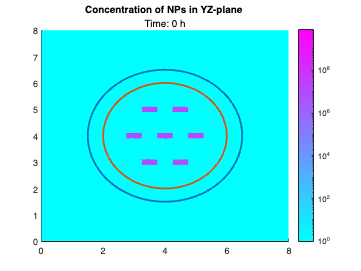

a = 1; b = 409; c = 1;

figure
pdeplot(model,'XYData',results.NodalSolution(:,a));
set(gca,'ColorScale','log')
caxis([10^0 7.97*10^9])
title('Concentration of NPs in YZ-plane ','Time: 0 h');
hold on
[xc, yc] = circle([4 4], 2.5,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
plot(xc, yc, '-','linewidth',2);
[xc2, yc2] = circle([4 4], 2,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
plot(xc2, yc2, '-','linewidth',2);
hold off

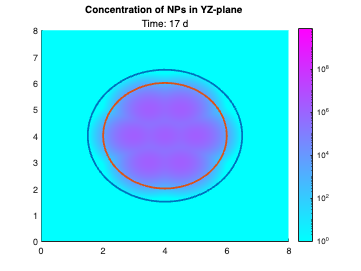


pdeplot(model,'XYData',results.NodalSolution(:,b));
set(gca,'ColorScale','log')
caxis([10^0 7.97*10^9])
title('Concentration of NPs in YZ-plane ','Time: 17 d');
hold on
[xc, yc] = circle([4 4], 2.5,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
plot(xc, yc, '-','linewidth',2);
[xc2, yc2] = circle([4 4], 2,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
plot(xc2, yc2, '-','linewidth',2);
hold off

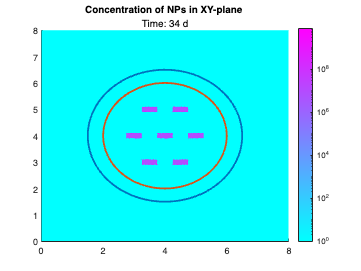


pdeplot(model,'XYData',results.NodalSolution(:,c));
set(gca,'ColorScale','log')
caxis([10^0 7.97*10^9])
title('Concentration of NPs in XY-plane ','Time: 34 d');
hold on
[xc, yc] = circle([4 4], 2.5,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
plot(xc, yc, '-','linewidth',2);
[xc2, yc2] = circle([4 4], 2,100); % radius determines radius of circles filling the area, n = number of coordinates calculated, less is less smooth circle (hoekig)    
plot(xc2, yc2, '-','linewidth',2);
hold off


% 
% pdeplot(model,'XYData',results.NodalSolution(:,817));
% caxis([0 7.53*10^9])
% title('Concentration of NPs in XY-plane ','Time: 34 d');


Error using load
Unable to find file or directory 'Cresults_default.mat'.

figure
plot(runData.timePoints,Cresults_default.solMax,'LineWidth',3)
hold on
plot(runData.timePoints,Cresults_default.averageC,'LineWidth',3)
%hold on
plot(runData.timePoints,Cresults_default.minC,'LineWidth',3)
plot(runData.timePoints,modelData.solMax,'LineWidth',3)
plot(runData.timePoints,YZ_averageC,'LineWidth',3)
plot(runData.timePoints,YZ_minC,'LineWidth',3)
title('Concentration in GTV over time')
txt = {'for XZ and YZ plane'};
subtitle(txt)
set(gca,'YScale','log')
ylim([10^0 10^11])
ylabel("Concentration (#NP/cm^3)")
xlabel("Time (min)") 
legend("c max XZ","c average XZ","c min XZ","c max YZ","c average YZ","c min YZ")

## Spread of heat: Intersection

solMin = min(Cresults);
solMax = max(Cresults);
Xmesh = model.Mesh.Nodes(1,:);
Ymesh = model.Mesh.Nodes(2,:);
Xnodes = Xmesh';
Ynodes = Ymesh';
spread = results.NodalSolution(:,409);
heatspread = [Xnodes Ynodes spread];
for i = 1:length(heatspread(:,2))
    if heatspread(i,2) >= 4.05 || heatspread(i,2) <= 3.95
        heatspread(i,2) = 0;
    end
end
heatspread(any(heatspread(:,2)==0,2),:) = [];
heatspread = sortrows(heatspread,1);

%%%%%% standard %%%%%
spread = Cresults_default.Cresults(:,409);
heatspread_default = [Cresults_default.Xnodes Cresults_default.Ynodes spread];
for i = 1:length(heatspread_default(:,2))
    if heatspread_default(i,2) >= 4.03 || heatspread_default(i,2) <= 3.97
        heatspread_default(i,2) = 0;
    end
end
heatspread_default(any(heatspread_default(:,2)==0,2),:) = [];
heatspread_default = sortrows(heatspread_default,1);


figure
plot(heatspread_default(:,1),heatspread_default(:,3),'-','Linewidth',2)
hold on
plot(heatspread(:,1),heatspread(:,3),'-','Linewidth',1.5)
annotation("line",[0.324 0.324],[0.1085 0.8862]);
annotation("line",[0.712 0.712],[0.1085 0.8862]);
title('Spread of NPs at t = 17 ays')
txt = {'intersection through centre of tumour'};
subtitle(txt)
set(gca,'YScale','log')
ylim([10^0 10^11])
ylabel("Concentration (#NP/cm^3)")
xlabel("Distance x-direction (cm)")
legend("XZ","YZ")

function Cinit_tumor = Cinit_NP2(location,x0,y0,SourceValue)
        % heaviside gives 0 if the equation of radius - the circle is smaller than 0 (location is outside the circle)
        % and gives 1*Sourcevalue for all locations within the circle
        % third term represents a normal distribution over x and y, resulting in a smooth distribution
        % with the coordinations of the node as the maximum of the Gaussian peak (=1).
        % This needs to be multiplied with the value of the concentration of the injection
        Near_seed = 0;
            for c1 = 1:(length(x0))
                x1(c1,1) = x0(c1,1);
                x2(c1,1) = x0(c1,2);
                y1(c1,1) = y0(c1,1);
                y3(c1,1) = y0(c1,3);
            end
        for i = 1:length(x1)
                Cinit_seed = (heaviside(location.x-x1(i)).*heaviside(x2(i)-location.x).*heaviside(location.y-y1(i)).*heaviside(y3(i)-location.y));
                Near_seed = Near_seed + Cinit_seed;
        end
        Cinit_tumor = Near_seed.*SourceValue ;

end